clc, clear vars, close all


## **Grabar un audio por el micrófono**

dlg_title = 'Grabar audio - micrófono';
prompt = { 'Frec. Muestreo','Bits/muestra', 'Núm. Canales','Tiempo Grab. (s)'};
num_lines = 1;
defaultans = {'44100', '16','1', '3'};

answer = inputdlg(prompt,dlg_title,num_lines,defaultans);

Fs1=str2num(answer{1});    % Frecuencia de muestreo   
nBit1=str2num(answer{2});   % Número de bits por muestra
nChan1=str2num(answer{3});   % Número de canales
tRec1=str2num(answer{4});    % Tiempo de grabación en s.

aud1 = audiorecorder(Fs1,nBit1,nChan1); % Crear un objeto audiorecorder

disp('Iniciando la grabación...');

Iniciando la grabación...



recordblocking(aud1, tRec1); % Grabar  audio

disp('Fin de la grabación.');

Fin de la grabación.



x1 = getaudiodata(aud1); % Obtener los datos de la señal x1

audiowrite('miAudio.wav',x1,Fs1); % Guardar los datos en un archivo WAV


## Visualizar la señal de audio - micrófono

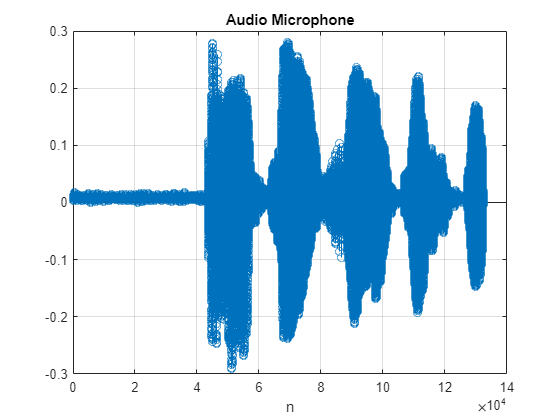

n = 0:length(x1)-1;
stem(n,x1); grid on; title('Audio Microphone'); xlabel('n')

## **Leer Archivo de Audio**

[filename, pathname] = uigetfile('*.*', 'Seleccione un archivo de audio'); % Seleccionar el archivo de audio
[x2,Fs2] = audioread(fullfile(pathname,filename)); % Leer el archivo de audio

% Información del archivo de audio.
info = audioinfo(filename)

info = struct with fields:
             Filename: 'C:\Users\PC\OneDrive - correounivalle.edu.co\Documentos\Asignaturas\SeñalesSistemas_II\Programas\miAudio.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 132300
             Duration: 3
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


## **Reproducir el Audio**

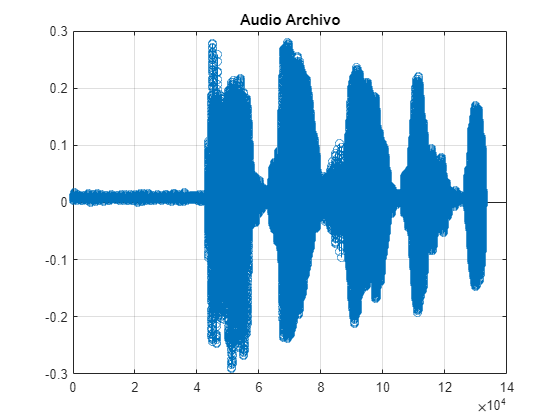

sound(x2,Fs2);% Reproducir el audio
%t = (0:length(x2)-1)/Fs2; % Crear un vector de tiempo
n2 = 0:length(x2)-1; % Crear un vector de instantes 

% Visualizar la señal de audio x2
figure; stem(n2,x2);title('Audio Archivo');grid on 